load('AnalogData.mat');
rawData = out.AnalogData

rawData = 42021×2 uint16 matrix
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


Nround = 21;
Nsample = 2001;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData = 42021×1 uint16 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


analogs = rawData(:, 2)

analogs = 42021×1 uint16 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


anaData = reshape(analogs, [Nsample, Nround])'

anaData = 21×2001 uint16 matrix
      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0
      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0
    183    186    184    181    185    185    174    181    177    181    182    182    181    175    177    176    182    183    184    178    182    181    179    182    173    178    185    177    182    179    181    178    181    176    182    175    179    182


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


meanVoltDataVSRef = ((mean(voltData, 2)/3.3) *100)

meanVoltDataVSRef =          0
         0
    4.3940
    9.4785
   15.1587
   19.8839
   25.1501
   30.0984
   35.3399
   40.7316


measureX = 0 : 5 : 100

measureX =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


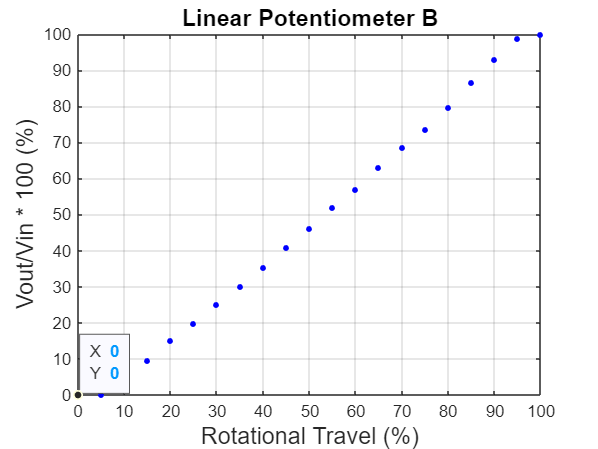

% Plotting
measureGraph = plot(measureX, meanVoltDataVSRef, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% Add on
xticks(0:10:100);
xticklabels(0:10:100);
datatip(measureGraph);
grid on;
title('Linear Potentiometer B', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14);

% Load PlotData
load('linearB.mat');
load('x.mat');

% Read and plot datasheet
datasheetValue = linearB

datasheetValue =     0.0100    0.0400    0.7200    1.6600    3.6400    6.3300   11.7100   20.0700   30.0100   38.8300   49.0600   56.3200   63.7200   71.1300   79.2400   86.5000   94.1700   97.5700   99.2500   99.5000   99.6000


datasheetX = x;

% Calculate Errors
err = 20/100 * datasheetValue

err =     0.0020    0.0080    0.1440    0.3320    0.7280    1.2660    2.3420    4.0140    6.0020    7.7660    9.8120   11.2640   12.7440   14.2260   15.8480   17.3000   18.8340   19.5140   19.8500   19.9000   19.9200


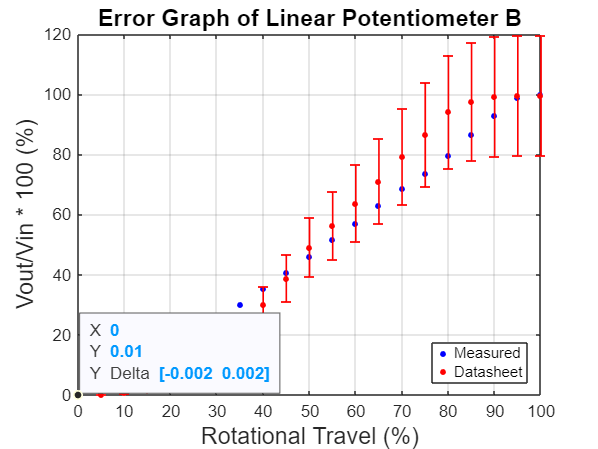

% Plotting Graph
measureGraph;
hold on;
datasheetGraph = plot(datasheetX, datasheetValue, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
errorGraph = errorbar(measureX, datasheetValue, err, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
datatip(measureGraph);
datatip(datasheetGraph);
datatip(errorGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Error Graph of Linear Potentiometer B', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 
legend('Measured', 'Datasheet', 'Location', 'southeast');